# Carro pêndulo

Bruno Monteiro Bonetti - 232488 

Luis Paulo Siqueira Silva - 183045

## Modelagem

clc; close all; clear all;

mc = 1.5; % mass of the cart
mp = 0.5; % mass of the pendulum
g = 9.82; % gravity
L = 1;    % length of the pendulum
d1 = 1e-2;  % damping of the cart displacement
d2 = 1e-2; % damping of the joint

A = [0,   0,   1,    0;
    0,   0,   0,    1;
    0,   g*mp/mc,   -d1/mc, -d2/(L*mc);
    0,   g*(mc+mp)/(L*mc),  -d1/(L*mc), -d2*(mc+mp)/(L^2*mc*mp)]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067   -0.0267



B = [ 0; 0; 1/mc;  1/(L*mc)];

C = [0 1 0 0];

D = 0;

C_q1 = [1 0 0 0];

sys = ss(A, B, C, D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


## Análise de estabilidade

poles = pole(sys)

poles =    -3.6327
    3.6043
   -0.0050
         0


eigenvalues = eig(A)

eigenvalues =          0
   -3.6327
    3.6043
   -0.0050


zeros = zero(sys)

zeros = 1.0e-16 *

    0.2473
         0



% como tem polo maior que 0, não é estavel (todos os polos têm
% que estar no semiplano esquerdo)

## Funções de transferência

%% questao 1.2

[b, a] = ss2tf(A, B, C, D);
ft_q2 = tf(b, a)


ft_q2 =
 
    0.6667 s^2 + 2.333e-17 s + 3.186e-16
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties



[zeros, poles, gain] = zpkdata(ft_q2, 'v');

zeros(abs(zeros) < 1e-2) = 0;
poles(abs(poles) < 1e-2) = 0;

new_tf = zpk(zeros, poles, gain);
new_tf = tf(new_tf)


new_tf =
 
           0.6667 s^2
  -----------------------------
  s^4 + 0.02833 s^3 - 13.09 s^2
 
Continuous-time transfer function.
Model Properties



simplified_new_tf = minreal(new_tf)


simplified_new_tf =
 
          0.6667
  -----------------------
  s^2 + 0.02833 s - 13.09
 
Continuous-time transfer function.
Model Properties



[zeros, poles, gain] = zpkdata(simplified_new_tf, 'v');


Houve cancelamento de polos e zeros porque a simplificação considerou que os efeitos desses termos insignificantes (em magnitude) podem ser ignorados sem alterar significativamente o comportamento dinâmico do sistema. Isso resulta em uma função de transferência mais simples, mas que mantém as características essenciais do sistema em frequências relevantes.

## Questão 1.3

[b_q1, a_q1] = ss2tf(A, B, C_q1, D);
ft_q1 = tf(b_q1, a_q1)


ft_q1 =
 
       0.6667 s^2 + 0.01333 s - 6.547
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties



ft_q2


ft_q2 =
 
    0.6667 s^2 + 2.333e-17 s + 3.186e-16
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties


## Questão 1.4

[zeros, poles, gain] = zpkdata(ft_q1, 'v')

zeros =    -3.1437
    3.1237


poles =          0
   -3.6327
    3.6043
   -0.0050


gain = 0.6667

[zeros, poles, gain] = zpkdata(ft_q2, 'v')

zeros = 1.0e-07 *

  -0.0000 + 0.2186i
  -0.0000 - 0.2186i


poles =          0
   -3.6327
    3.6043
   -0.0050


gain = 0.6667

O polos são iguais pois dependem apenas da matriz A, como podemos ver no denominador da equação de função de transferencia a partir do espaço de estados:

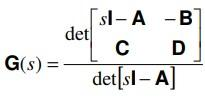

Já os zeros, dependerm de todas as matrizes, como se pode ver no numerador da mesma equação. Assim, variando C, varia-se os zeros da função.

## Questão 2.1

Usando os valores passados das matrizes A, B, C, D, construimos o seguinte no Simulink:

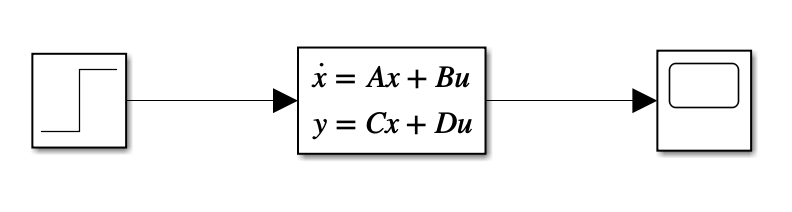

Plotando a resposta ao degrau, obtemos o seguinte:

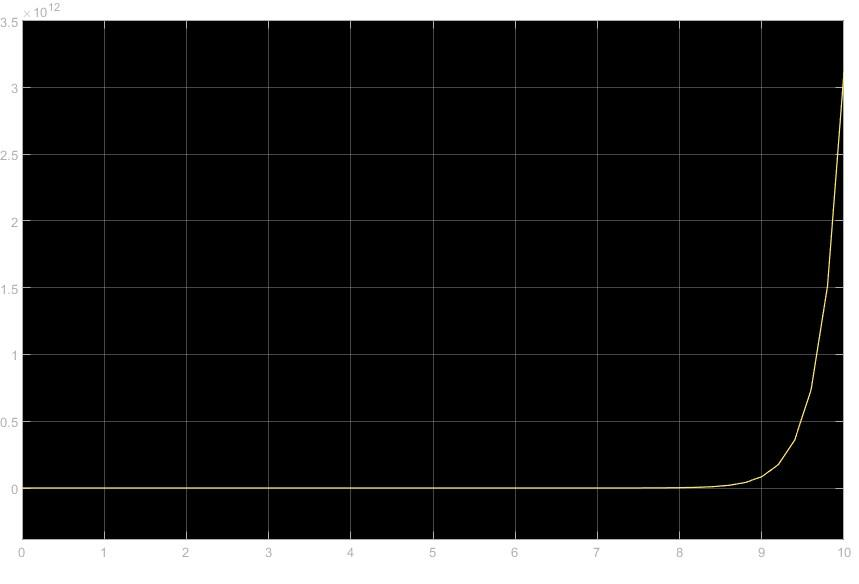

Verifica-se que o sistema é instável, com sua amplitude de resposta tendendo ao infinito.

## Questão 2.2

% rlocus(ft_q2)
% grid on;
% 
% rlocus(simplified_new_tf)
% grid on;

Com o plot do lugar das raízes das duas funções de tranferência (a primeira sendo o sistema original, e a segunda sendo a função em que primeiro aproximamos para zero os polos e zeros, e depois fizemos o cancelamento), fica notável a diferença entre as duas. Na primeira, temos mais polos e zeros, enquanto que na segunda eles foram reduzidos mas permanecem no semiplano direito. 

Quanto à capacidade de um controlador P estabilizar a malha fechada, o grupo entende que não é possível pois os polos se encontram no semiplano direito, o que já indica instabilidade. O lugar das raízes indica que, para K>0, os polos dominantes permanecem no semiplano direito. Assim, um controlador proporcional simples P não é suficiente para estabilizar o sistema.

## Questão 2.3

% sisotool(ft_q2)

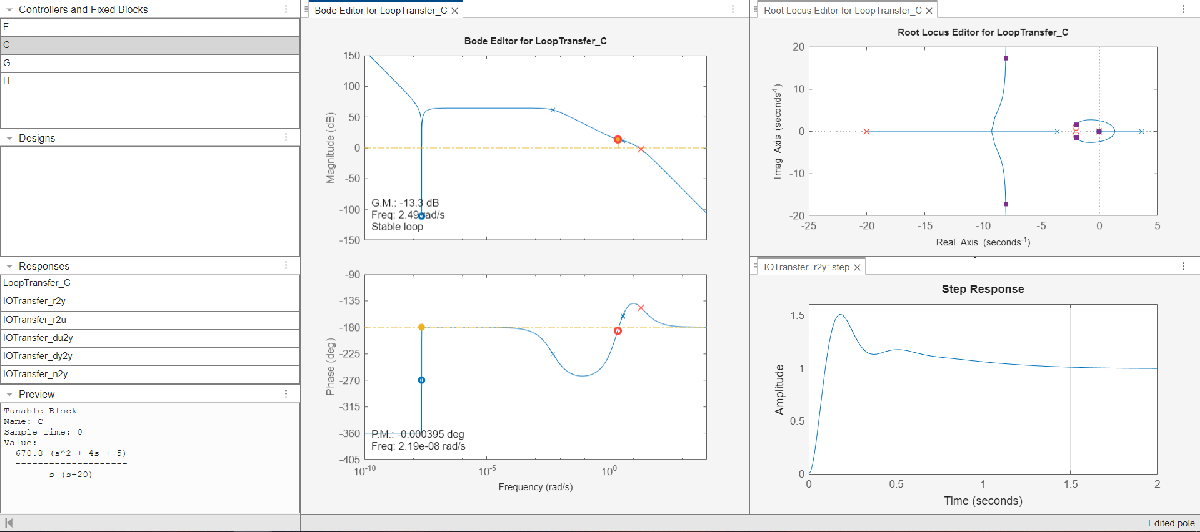

O controlador encontrado tem a seguinte função de transferência:


$$\frac{670.84(s^2 + 4s+5)}{s(s+20)}$$


O ganho estabilizante encontrado foi, portanto, de 670.84.

## Questão 2.4

Exportamos o controlador encontrado no item anterior para o simulink, e obtivemos o seguinte diagrama de blocos:

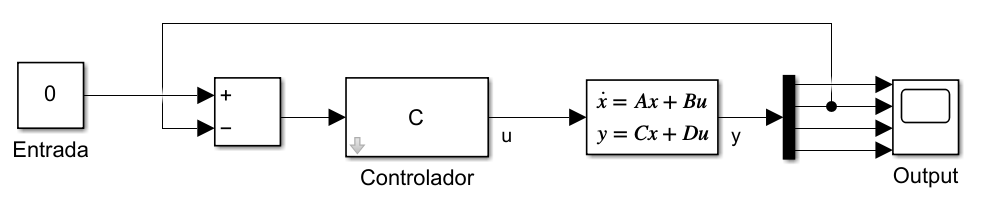

Então, a saída do estado q2 é mostrada abaixo.

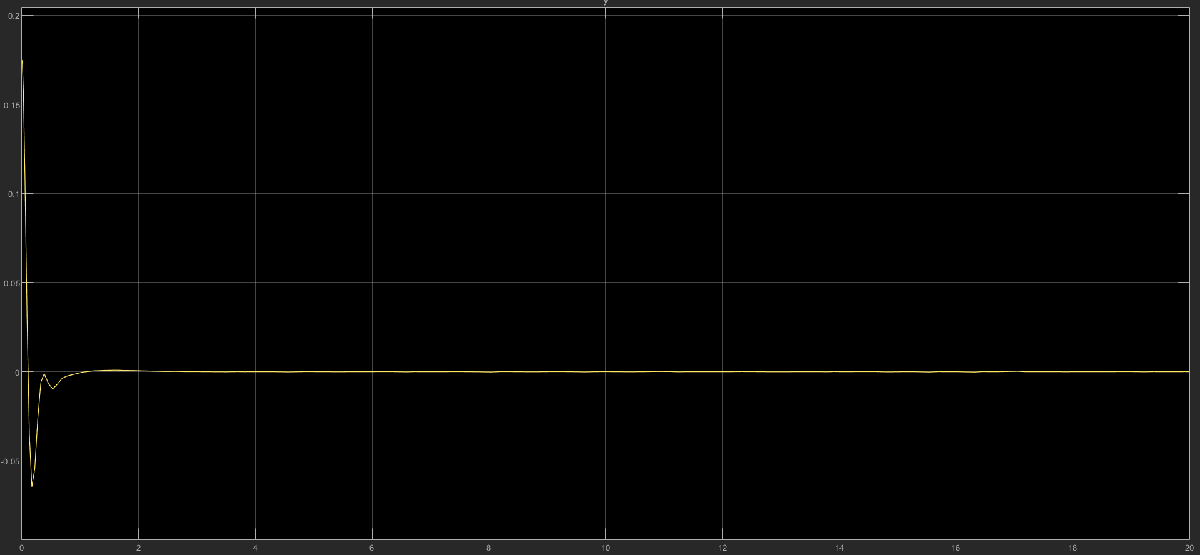

Percebe-se que ela se estabiliza no set point de 0, mesmo com a condição inicial de 0.174533 rad (10°), como era esperado. 

Simulando 100s, obtivemos o seguinte, mostrando todos os estados:

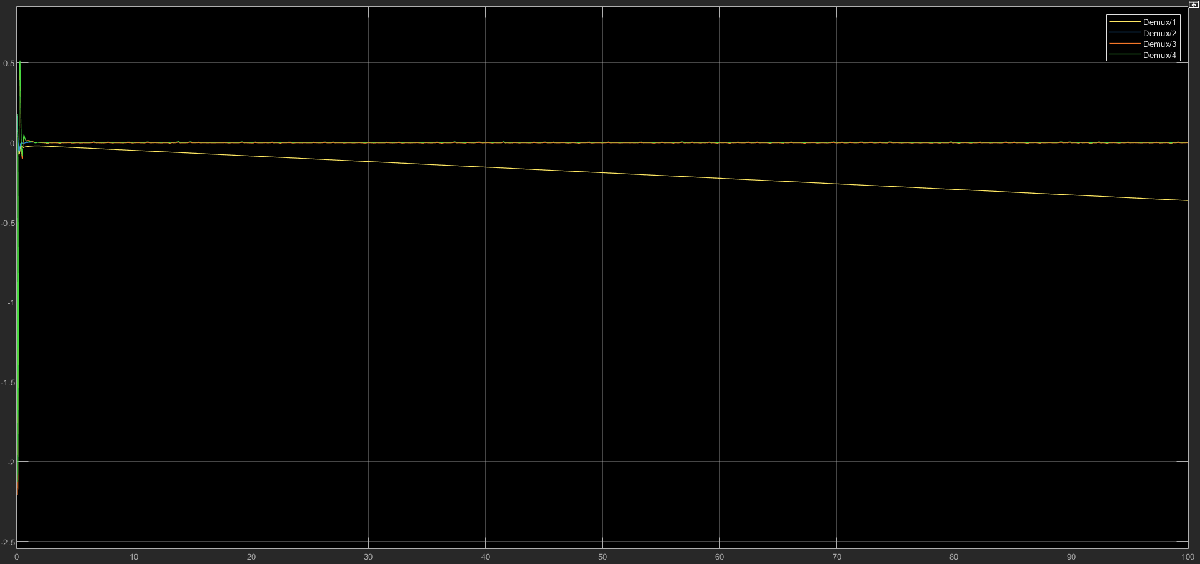

Aqui, observamos que não são todos os estados que convergem para zero. O estado q1 possui um decaimento linear com o passar do tempo, como pode ser visto na figura. Isso se deve por conta de não ter sido realizado o controle sobre a posição do carrinho, que é justamente o estado q1. Para evitar esse problema, basta realizar um controle, de forma similar à realizada para o pêndulo, só que para a posição do carrinho. Dessa forma, o estado q1 passaria a tender a zero também.

## Questão 3.1

cont_q1 = ctrb(A,B)

cont_q1 =          0    0.6667   -0.0089    2.1824
         0    0.6667   -0.0222    8.7295
    0.6667   -0.0089    2.1824   -0.1455
    0.6667   -0.0222    8.7295   -0.5383


rank(cont_q1)

ans = 4


obsv_q1 = obsv(A, C_q1)

obsv_q1 =     1.0000         0         0         0
         0         0    1.0000         0
         0    3.2733   -0.0067   -0.0067
         0   -0.1091    0.0001    3.2736


rank(obsv_q1)

ans = 4

Por possuir o rank cheio, tanto para a controlabilidade quanto para a observabilidade, podemos afirmar que para a saída q1, o sistema é controlável e observável.

cont_q2 = ctrb(A,B)

cont_q2 =          0    0.6667   -0.0089    2.1824
         0    0.6667   -0.0222    8.7295
    0.6667   -0.0089    2.1824   -0.1455
    0.6667   -0.0222    8.7295   -0.5383


rank(cont_q2)

ans = 4


obsv_q2 = obsv(A, C)

obsv_q2 =          0    1.0000         0         0
         0         0         0    1.0000
         0   13.0933   -0.0067   -0.0267
         0   -0.3710    0.0002   13.0941


rank(obsv_q2)

ans = 3

Como a matriz A e B não mudam para a saída q2, o sistema continua sendo controlável. Porém, como a matriz C muda e o número de rank não é cheio, temos que, para essa saída, o sistema não é observável.

## Questão 3.2

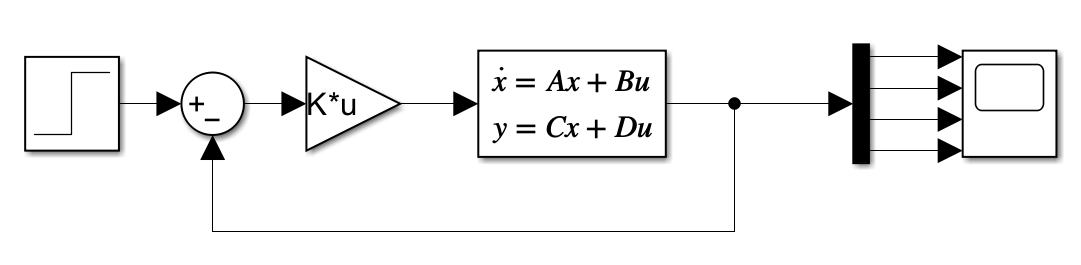

polos_desejados = [-1, -2, -1.5, -3]

polos_desejados =    -1.0000   -2.0000   -1.5000   -3.0000


K = place(A, B, polos_desejados)

K =    -1.3747   51.0835   -3.4497   14.6497


eig(A-B*K)

ans =    -3.0000
   -2.0000
   -1.5000
   -1.0000


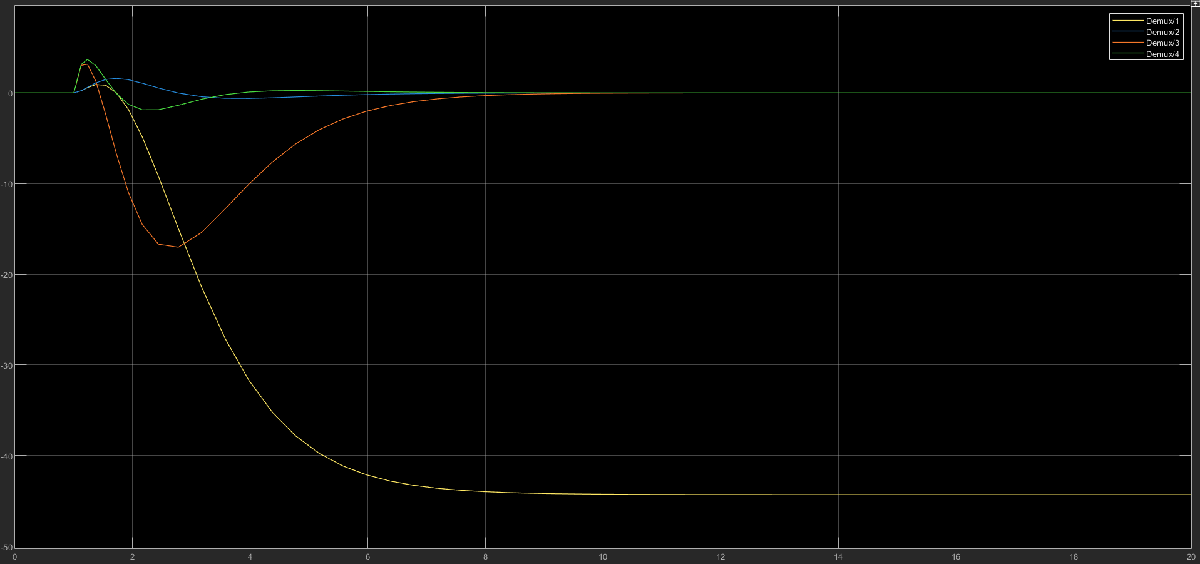

## Questão 3.3

Escolhendo novos polos, agora dois pares complexos, obtemos o seguinte:

polos_desejados2 = [-8-1i, -8+1i, -10-2i, -10+2i];
K2 = place(A,B, polos_desejados2)

K2 = 1.0e+03 *

   -1.0326    1.7948   -0.4549    0.5088


eig(A-B*K2)

ans =  -10.0000 + 2.0000i
 -10.0000 - 2.0000i
  -8.0000 + 1.0000i
  -8.0000 - 1.0000i


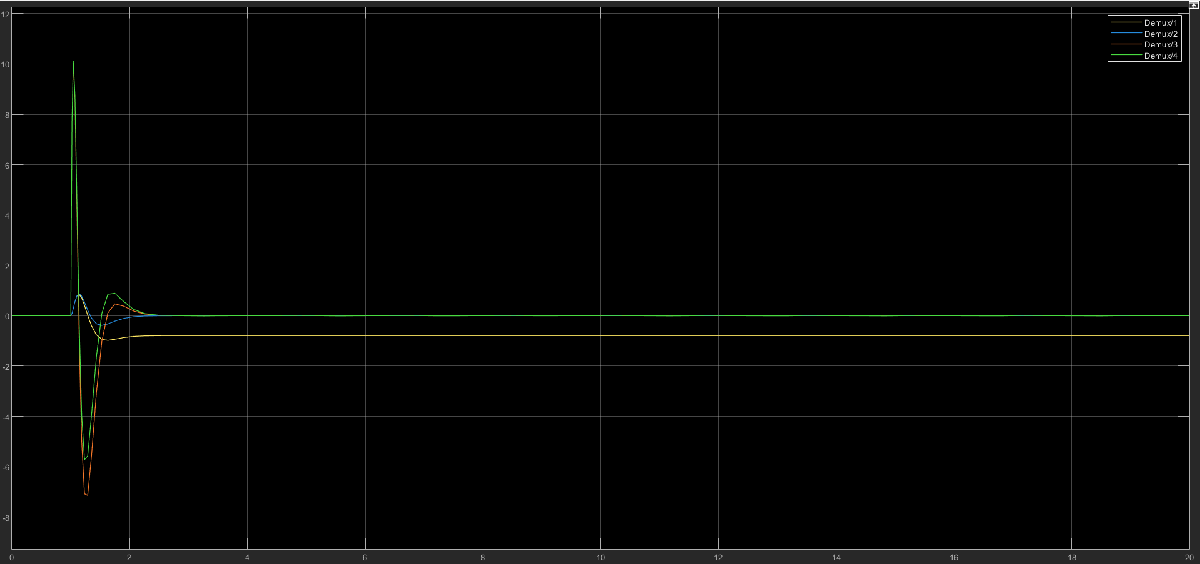

## Questão 3.4

Feito na questao3_4.m e questao3_4_simu.smx de mesmo nome. Podemos mostrar tanto os gráficos feitos pelo professor, quanto o degrau e constante 0 do simulink. Para rodar o simulink, precisa rodar antes o .m . O controlador obtido é o seguinte: 

K =  -10.0000   92.7912  -12.2159   27.9026

Usou-se rho = 100 e R = 1. Depois com o script de normalização, encontrou-se que N_ = -10.

## Questão 3.5

Aqui acredito que basta chutar outros valores de rho. Tem que ser feito.

## Questão 3.6

Colocamos o K do LQR obtido [-9.9999999999996145, 92.791161254939809, -12.215905748548041, 27.902583587911245] no arquivo disponibilizado pelo professor e a faixa de ângulo em que foi possível obter estabilidade no carrinho foi de -0.93 rad (-53,28°) até  0.793 rad (45,435553 °). Os resultados são mostrados a seguir.

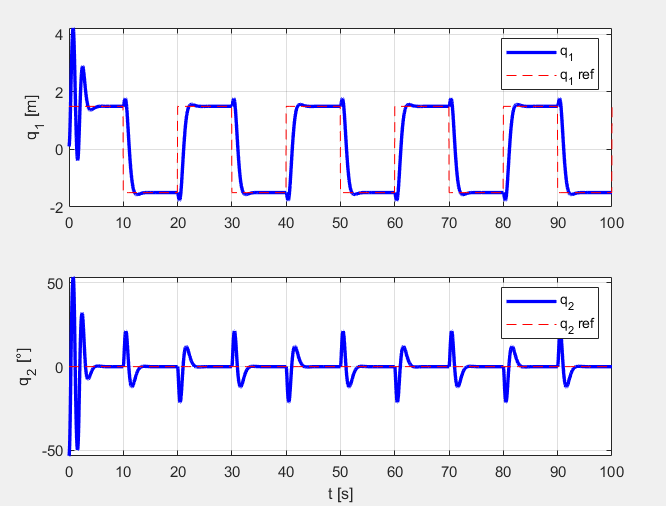

Ângulo inicial de -0.93 rad.

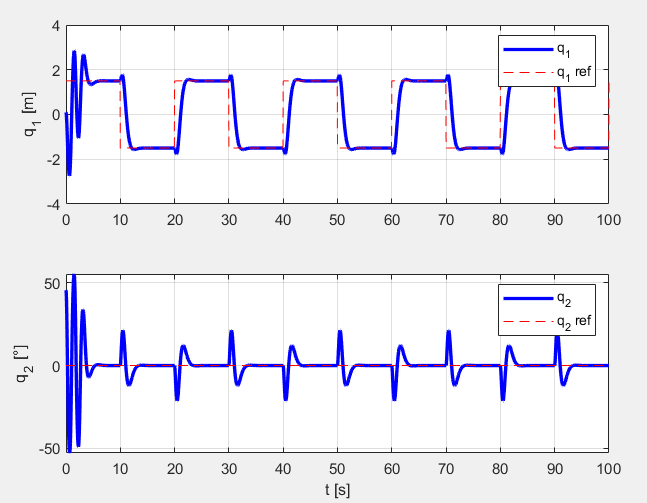

Ângulo inicial de 0.793 rad.

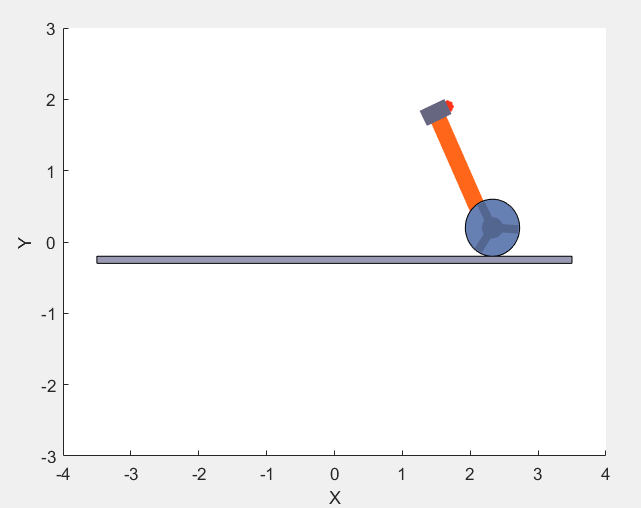

Sistema carro-pêndulo simulado.